# `Problem 1: Basic Plant Response Analysis`

###  Open-loop Analysis:

-  Plot the step response of the open-loop system

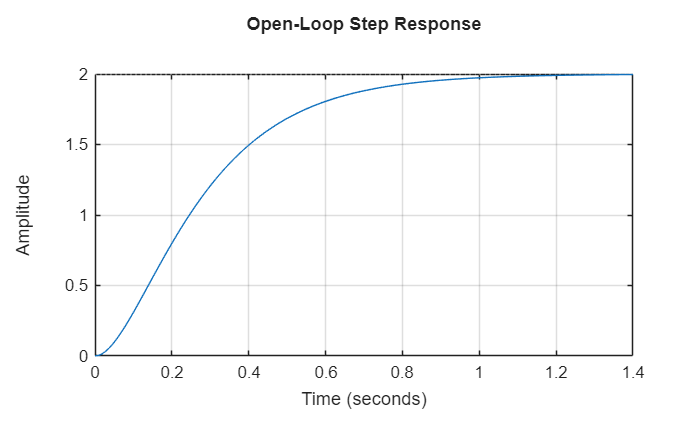

% Create G(s) = 100/( s^2 + 15*s + 50)
num = 100;
den = [1 15 50];
G = tf(num ,den);

% Generate Step-Response of transfer function
step(G)
grid on
title('Open-Loop Step Response')

- Calculate and report: rise time, settling time, peak overshoot, and steady-state error

% Display step response information
info = stepinfo(G) ;
fprintf ('Rise Time : %.3f s\n', info.RiseTime ) ;

Rise Time : 0.518 s


fprintf ('Settling Time : %.3f s\n', info.SettlingTime ) ;

Settling Time : 0.920 s


fprintf ('Overshoot : %.2f%% \n', info.Overshoot ) ;

Overshoot : 0.00% 


fprintf ('Peak : %.3f\n', info.Peak ) ;

Peak : 1.998


SP = 1; % define setpoint
[y, ~] = step(SP * G);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Steady State Error: %.3f\n', steady_state_error);

Steady State Error: 0.993


### P Controller Design:

- Design a proportional controller with Kp = 0.5

C = tf(0.5, 1) ; % Proportional controller Kp = 0.5
sys1 = feedback ( C * G , 1) ; % Closed - loop system

- Plot the closed-loop step response

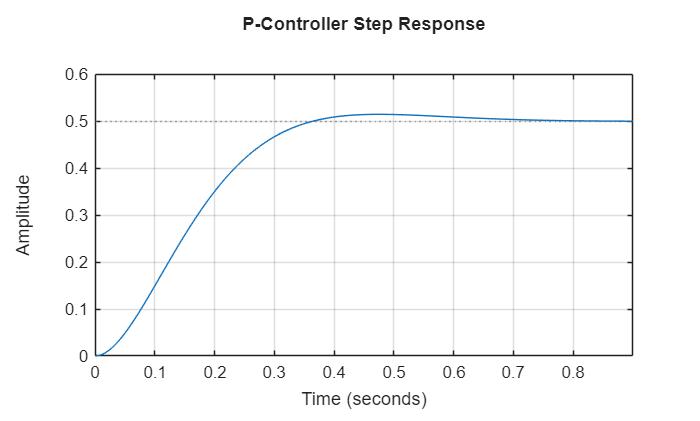

step(sys1)
grid on
title('P-Controller Step Response')

- Report the performance metrics and steady-state error

% Display step response information
info = stepinfo(sys1) ;
fprintf ('Rise Time : %.3f s\n', info.RiseTime ) ;

Rise Time : 0.229 s


fprintf ('Settling Time : %.3f s\n', info.SettlingTime ) ;

Settling Time : 0.574 s


fprintf ('Overshoot : %.2f%%\ n', info.Overshoot ) ;

Overshoot : 2.84%

fprintf ('Peak : %.3f\n', info.Peak ) ;

Peak : 0.514


SP = 1; % define setpoint
[y, ~] = step(SP * sys1);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Steady State Error: %.3f\n', steady_state_error);

Steady State Error: 0.500


- Explain why steady-state error exists with only P control

*With P control, control depends on error. If the error was to be zero, the control input would also be zero.Therefore, a non-zero error must remain.*

## PI Controller Design:

- Add integral action with Kp = 0.5, Ki = 1.5

% Create PI controller : Kp =0.5 , Ki =1.5
C1 = pid (0.5 , 1.5 , 0) ;
sys2 = feedback ( C1 * G , 1) ; % Closed - loop system

- Plot the closed-loop step response

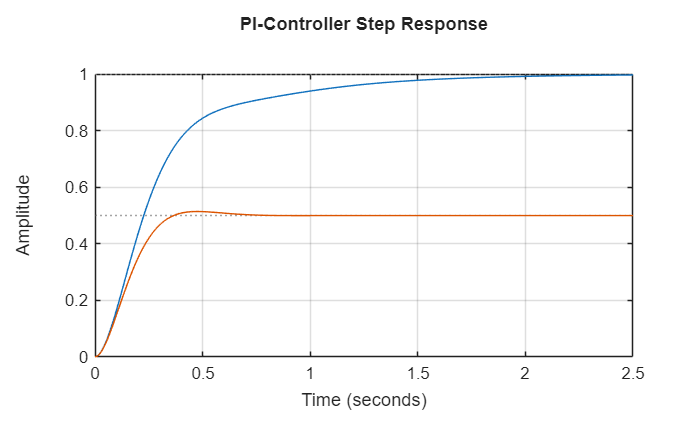

step(sys2, sys1) % Red line for P-Controller
grid on
title('PI-Controller Step Response')

% Display step response information
info = stepinfo(sys1) ;
fprintf ('Rise Time : %.3f s\n', info.RiseTime ) ;

Rise Time : 0.229 s


fprintf ('Settling Time : %.3f s\n', info.SettlingTime ) ;

Settling Time : 0.574 s


fprintf ('Overshoot : %.2f%% \n', info.Overshoot ) ;

Overshoot : 2.84% 


fprintf ('Peak : %.3f\n', info.Peak ) ;

Peak : 0.514


SP = 1; % define setpoint
[y, ~] = step(SP * sys2);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Steady State Error: %.3f\n', steady_state_error);

Steady State Error: 0.004


- Discuss how integral action eliminated steady-state error

*The integral term accumulates error over time. If a steady-state error exists, its integral keeps growing, which increases the control action until the error is driven to zero.*

### PID Controller Tuning:

- Tune the complete PID controller to achieve: – Overshoot < 10% – Settling time < 2 seconds – Zero steady-state error

pidTuner(G, 'PID')

- Report your final Kp, Ki , Kd values

% Final PID gains
Kp = 0.9931;
Ki = 4.8444;
Kd = 0.044209;

fprintf('Final PID Gains:\n');

Final PID Gains:


fprintf('Kp = %.2f\n', Kp);

Kp = 0.99


fprintf('Ki = %.2f\n', Ki);

Ki = 4.84


fprintf('Kd = %.2f\n', Kd);

Kd = 0.04


-  Plot the final response with all metrics labeled

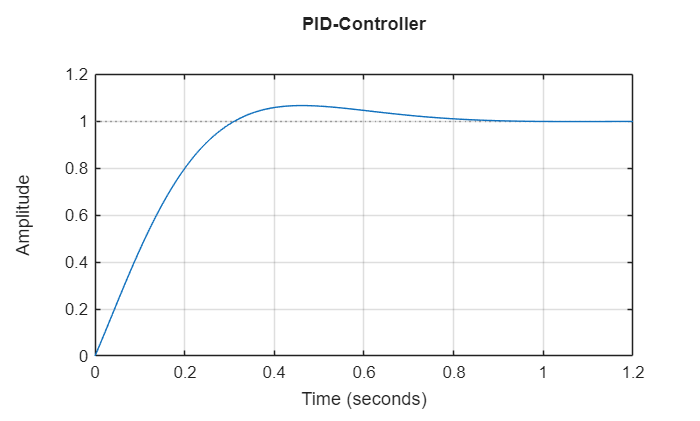

C_pid = pid(Kp,Ki,Kd);
C2 = feedback(C_pid*G, 1);
step(C2)
grid on
title('PID-Controller')

% Display step response information
info = stepinfo(C2) ;
fprintf ('Rise Time : %.3f s\n', info.RiseTime ) ;

Rise Time : 0.223 s


fprintf ('Settling Time : %.3f s\n', info.SettlingTime ) ;

Settling Time : 0.724 s


fprintf ('Overshoot : %.2f%% \n', info.Overshoot ) ;

Overshoot : 6.57% 


fprintf ('Peak : %.3f\n', info.Peak ) ;

Peak : 1.066


SP = 1; % define setpoint
[y, ~] = step(SP * C2);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Steady State Error: %.3f\n', steady_state_error);

Steady State Error: 0.002


# `Problem 2: Complex Input Tracking`

- Create a reference signal with multiple step changes: 

-  0 to 1 at t=0s

-  1 to 1.5 at t=5s

-  1.5 to 0.8 at t=10s

-  0.8 to 1.2 at t=15s

t = (0:0.01:20)'; % Time Vector
r = zeros(size(t)); % Creating Reference Signal

% Defining Reference Signal
for i = 1:length(t)
    if t(i) < 5
        r(i) = 1; % 0 to 1 at t=0
    elseif t(i) < 10
        r(i) = 1.5; % 1 to 1.5 at t=5
    elseif t(i) < 15
        r(i) = 0.8; % 1.5 to 0.8 at t=10
    else
        r(i) = 1.2; % 0.8 to 1.2 at t=15
    end
end


- Simulate using lsim() and plot reference vs output

- Calculate the tracking error over time

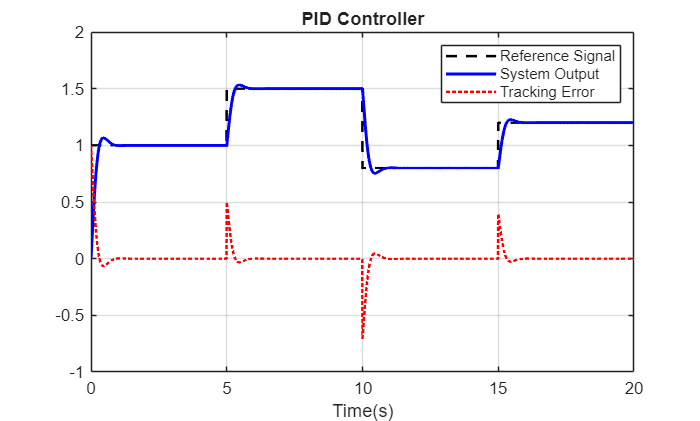

% Simulate system response using lsim
y = lsim( C2, r, t);

% Tracking error
e = r - y;

% Plot Output
figure;
plot(t, r, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
plot(t, e, 'r:', 'LineWidth', 1.5);
grid on;
xlabel('Time(s)');
title('PID Controller');
legend('Reference Signal', 'System Output', 'Tracking Error');
hold off;

###  Ramp Input:

- Test your PID with a ramp input: r(t) = 0.2t for 0 ≤ t ≤ 20s

- Plot reference, output, and error signals

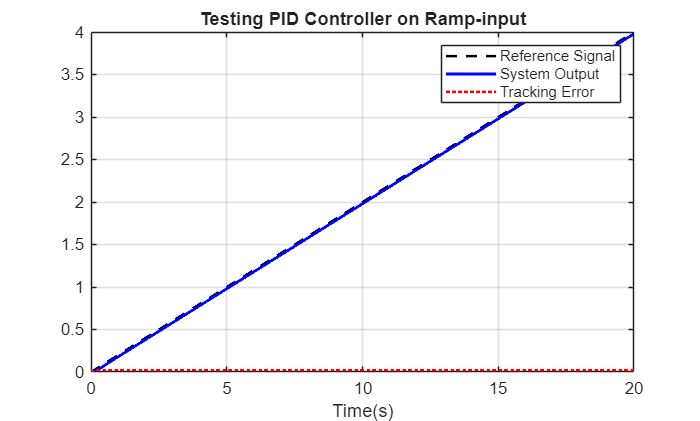

r = 0.2 * t; % Ramp input

% Simulate system response using lsim
y = lsim( C2, r, t);

% Tracking error
e = r - y;

% Plot Output
figure;
plot(t, r, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
plot(t, e, 'r:', 'LineWidth', 1.5);
grid on;
xlabel('Time(s)');
title('Testing PID Controller on Ramp-input');
legend('Reference Signal', 'System Output', 'Tracking Error');
hold off;

-  Calculate the steady-state tracking error

fprintf('Steady-state ramp tracking error = %.4f\n', e(end));

Steady-state ramp tracking error = 0.0206


- Explain why PID may struggle with ramp tracking

*A PID-conroller adds one integrator. So, the closed-loop becomes TYPE-1, i.e., Constant steady state error for Ramp-inputs. Thus, PID may struggle with ramp tracking.*

### Sinusoidal Reference:

- Apply a sinusoidal reference: r(t) = sin(0.5t) for 0 ≤ t ≤ 20s

r = sin(0.5 * t); % Ramp input

% Simulate system response using lsim
y = lsim( C2, r, t);

% Tracking error
e = r - y;


- Plot the tracking performance

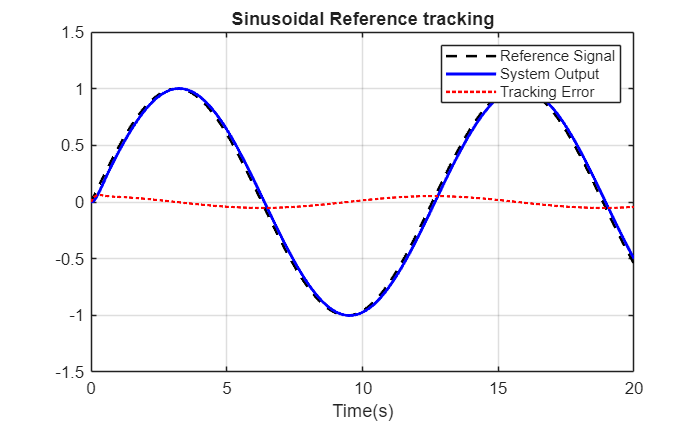

% Plot Output
figure;
plot(t, r, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
plot(t, e, 'r:', 'LineWidth', 1.5);
grid on;
xlabel('Time(s)');
title('Sinusoidal Reference tracking');
legend('Reference Signal', 'System Output', 'Tracking Error');
hold off;

-  Calculate the phase lag between reference and output

% Peak detection
[~, t_r] = findpeaks(r, t);
[~, t_y] = findpeaks(y, t);

% first matching peak
t_delay = t_r(1) - t_y(1);

% phase lag calculation
phase_lag_rad = 0.5 * t_delay;
phase_lag_deg = phase_lag_rad * (180/pi);

fprintf('Time delay = %.4f s\n', t_delay);

Time delay = -0.1100 s


fprintf('Phase lag  = %.2f degrees\n', phase_lag_deg);

Phase lag  = -3.15 degrees


- Discuss which PID parameter (P, I, or D) most affects sinusoidal tracking

***Derivative control**** most strongly affects sinusoidal tracking, as it provides phase lead and anticipates changes in the reference signal. Proportional control mainly improves amplitude tracking, while integral control introduces additional phase lag and is less suitable for sinusoidal references.*

# `Problem 3: Practical PID Implementation Challenges`

###  Observing Integral Windup (Without Anti-Windup):

- Design a PI controller with Kp = 5, Ki = 8 

- Apply a large step input (setpoint = 5) to intentionally cause saturation 

- Implement actuator saturation using max(min(u, 10), -10)

- Important: In your for-loop, calculate the unsaturated control signal u and the saturated signal usat, but continue integrating the error normally (without considering saturation) • Plot: reference, output, control signal (both saturated and unsaturated), and integral term over time

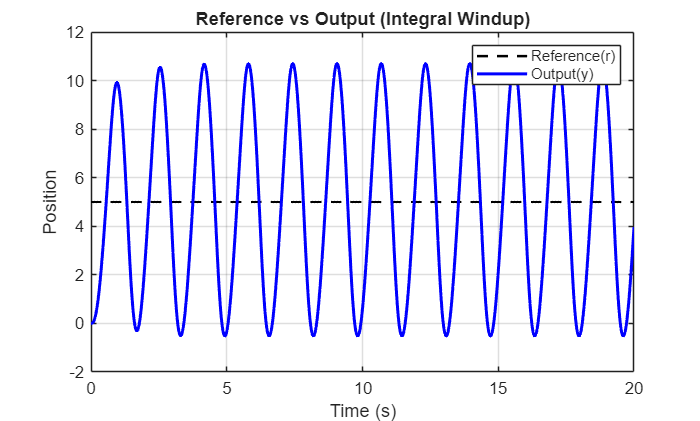

% Defining the Transfer function
G = tf(50, [1 8 25 20]);

% PI controller gains
Kp = 5;
Ki = 8;

% Simulation parameters
dt = 0.01;
t  = 0:dt:20;
N  = length(t);

r = 5 * ones(1, N); % Setpoint = 5

% Initialize signals
y = zeros(1,N); % output
y_dot = 0; % y_dot = dy/dt
y_ddot = 0; % y_ddot = d(y_dot)/dt . Similarly, y_tdot = d(y_ddot)/dt

e = zeros(1,N);
u_unsat = zeros(1,N);
u_sat = zeros(1,N);
I_term = zeros(1,N);

integral_error = 0;

% Time-domain simulation
for k = 1:N-1

    % Error
    e(k) = r(k) - y(k);

    % Integrate error (NO anti-windup)
    integral_error = integral_error + e(k)*dt;
    I_term(k) = Ki * integral_error;

    % Unsaturated control
    u_unsat(k) = Kp*e(k) + I_term(k);

    % Actuator saturation
    u_sat(k) = max(min(u_unsat(k), 10), -10);

    % Plant differential equation (Was Calculated Manually)
    y_tdot = 50*u_sat(k) - 20*y(k) - 25*y_dot - 8*y_ddot;

    % Integrate plant states
    y_ddot = y_ddot + y_tdot*dt;
    y_dot  = y_dot  + y_ddot*dt;
    y(k+1) = y(k)   + y_dot*dt;
end

% Plots
% Output vs reference
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Position');
title('Reference vs Output (Integral Windup)');
legend('Reference(r)','Output(y)');

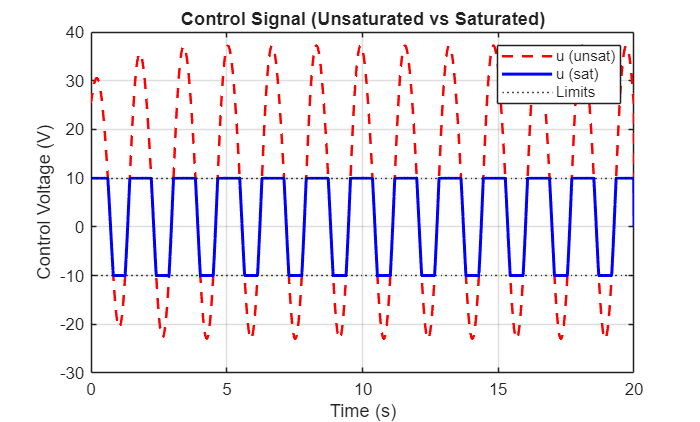

% Control signals
figure;
plot(t, u_unsat, 'r--', 'LineWidth', 1.5); hold on;
plot(t, u_sat, 'b', 'LineWidth', 1.8);
yline(10,'k:'); yline(-10,'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Voltage (V)');
title('Control Signal (Unsaturated vs Saturated)');
legend('u (unsat)','u (sat)','Limits');

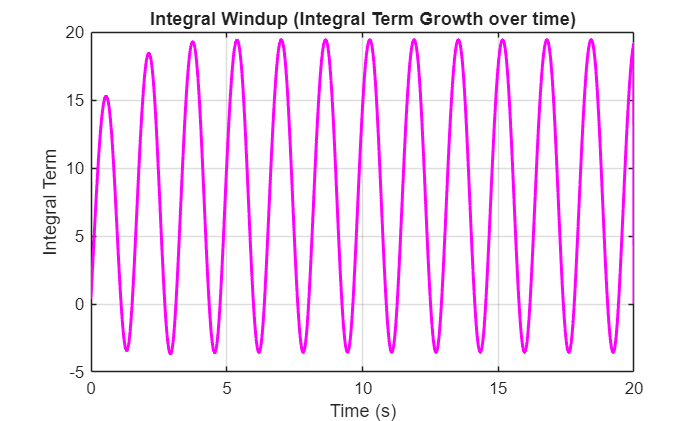

% Integral term
figure;
plot(t, I_term, 'm', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Integral Term');
title('Integral Windup (Integral Term Growth over time)');

- Observe and describe: 

`When does saturation occur? `

*Saturation occurs immediately at the step input.* *The large initial error (5 − 0 = 5) produces *

*u(0) = Kp⋅5 = 25  >  10*

`What happens to the integral term during saturation?`

*The integral term keeps increasing. Even though the actuator is stuck at ±10, the integrator continues accumulating*


$$\mathit{\mathbf{I}}=\int \mathit{\mathbf{e}}\;\textrm{dt}$$

$$\;\;\uparrow \uparrow$$


`How does this affect overshoot and settling time when the output finally approaches setpoint?`

*When the output approaches setpoint, error becomes really small. Though, the inegral term is large. Therefore, controller pushes system past the setpoint. Overshoot is quite large.*

*Consequently, the integral must unwind before the control stabilizes. Causing long oscillation and slower return to steady-state. Thus, settling time becomes significantly longer.*

### Implementing Anti-Windup:

- Use the same PI controller and input from part (a) 

- Now implement anti-windup using back-calculation method: d dt(integral term) = e(t) + 1 Kt (usat − u) where Kt is the tracking gain (try Kt = √ Ki) 

- The key difference: when u ̸= usat, the integral term stops accumulating normally 

- Plot the same signals as part (a) on a separate figure 

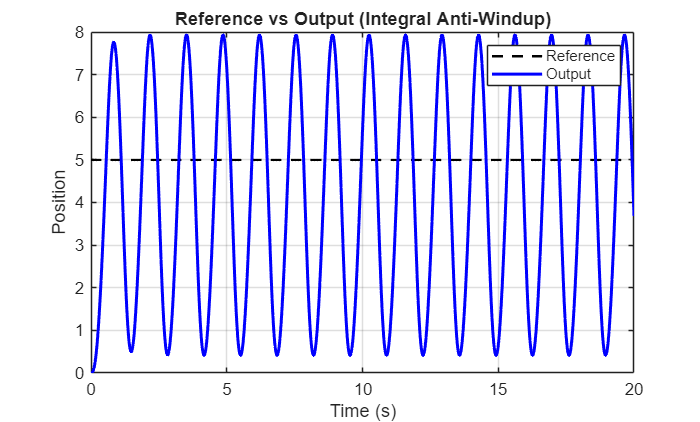

% PI controller gains
Kp = 5;
Ki = 8;
Kt = sqrt(Ki);

% Simulation parameters
dt = 0.01;
t  = 0:dt:20;
N  = length(t);

r = 5 * ones(1, N); % Setpoint = 5

% Initialize signals
y1 = zeros(1,N); % output
y1_dot = 0; % y_dot = dy/dt
y1_ddot = 0; % y_ddot = d(y_dot)/dt . Similarly, y_tdot = d(y_ddot)/dt

e1 = zeros(1,N);
u1_unsat = zeros(1,N);
u1_sat = zeros(1,N);
I1_term = zeros(1,N);

integral_error1 = 0;

% Time-domain simulation
for k = 1:N-1

    % Error
    e1(k) = r(k) - y1(k);

    % Unsaturated control
    u1_unsat(k) = Kp*e1(k) + Ki*integral_error1;

    % Actuator saturation
    u1_sat(k) = max(min(u1_unsat(k), 10), -10);

    % Ani-Windup back-calculation
    integral_error1 = integral_error1 + (e1(k) + (u1_sat(k) - u1_unsat(k))/Kt)*dt;
    I1_term(k) = Ki * integral_error1;

    % Plant differential equation (Was Calculated Manually)
    y1_tdot = 50*u1_sat(k) - 20*y1(k) - 25*y1_dot - 8*y1_ddot;

    % Integrate plant states
    y1_ddot = y1_ddot + y1_tdot*dt;
    y1_dot  = y1_dot  + y1_ddot*dt;
    y1(k+1) = y1(k)   + y1_dot*dt;
end

% Plots
% Output vs reference
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y1, 'b', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Position');
title('Reference vs Output (Integral Anti-Windup)');
legend('Reference','Output');

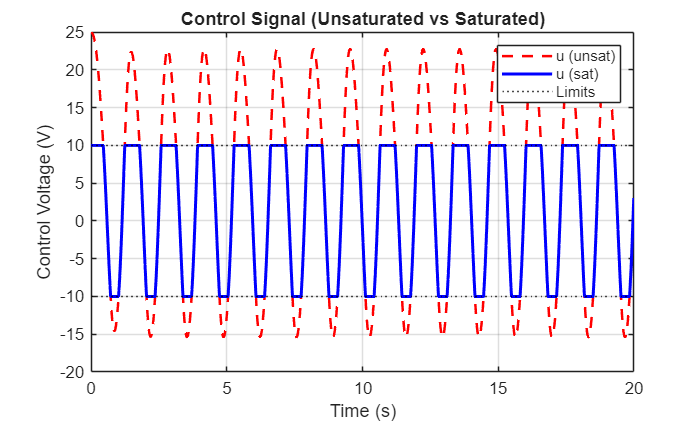

% Control signals
figure;
plot(t, u1_unsat, 'r--', 'LineWidth', 1.5); hold on;
plot(t, u1_sat, 'b', 'LineWidth', 1.8);
yline(10,'k:'); yline(-10,'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Voltage (V)');
title('Control Signal (Unsaturated vs Saturated)');
legend('u (unsat)','u (sat)','Limits');

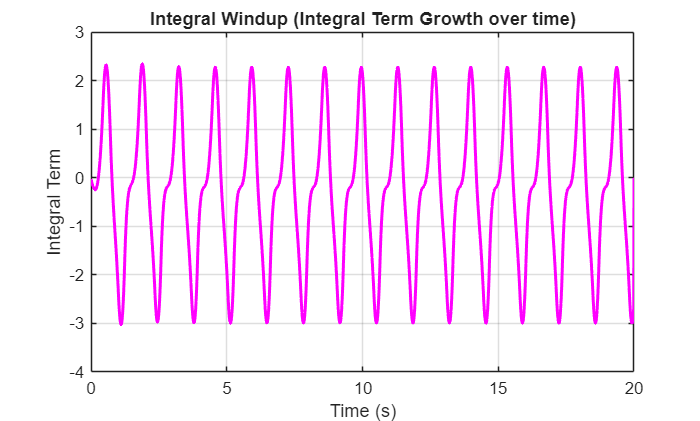


% Integral term
figure;
plot(t, I1_term, 'm', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Integral Term');
title('Integral Windup (Integral Term Growth over time)');

- Create a comparison plot showing both responses side-by-side 

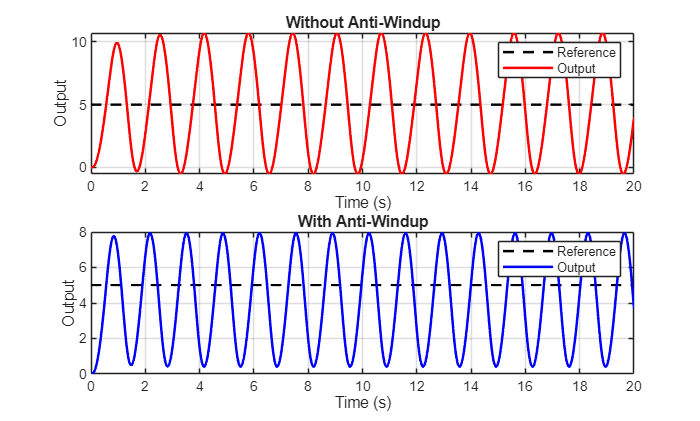

% Output response
figure;
subplot(2,1,1)
plot(t,r,'k--',t,y,'r','LineWidth',1.5)
grid on
title('Without Anti-Windup')
xlabel('Time (s)'), ylabel('Output')
legend('Reference','Output')

subplot(2,1,2)
plot(t,r,'k--',t,y1,'b','LineWidth',1.5)
grid on
title('With Anti-Windup')
xlabel('Time (s)'), ylabel('Output')
legend('Reference','Output')

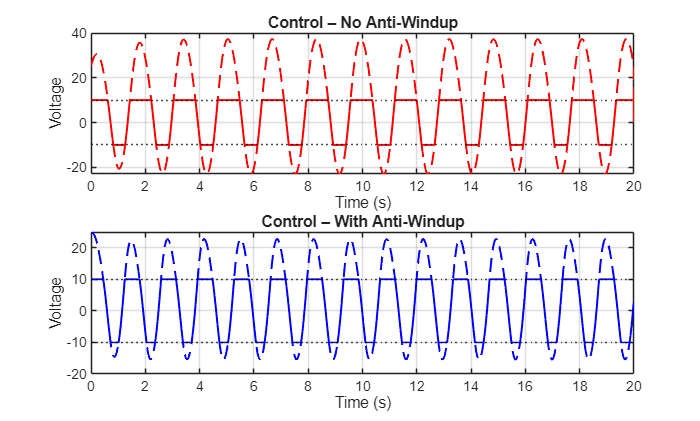

% Control Signals
figure;
subplot(2,1,1)
plot(t,u_unsat,'r--',t,u_sat,'r','LineWidth',1.2)
yline(10,'k:'), yline(-10,'k:')
grid on
title('Control – No Anti-Windup')
xlabel('Time (s)'), ylabel('Voltage')

subplot(2,1,2)
plot(t,u1_unsat,'b--',t,u1_sat,'b','LineWidth',1.2)
yline(10,'k:'), yline(-10,'k:')
grid on
title('Control – With Anti-Windup')
xlabel('Time (s)'), ylabel('Voltage')

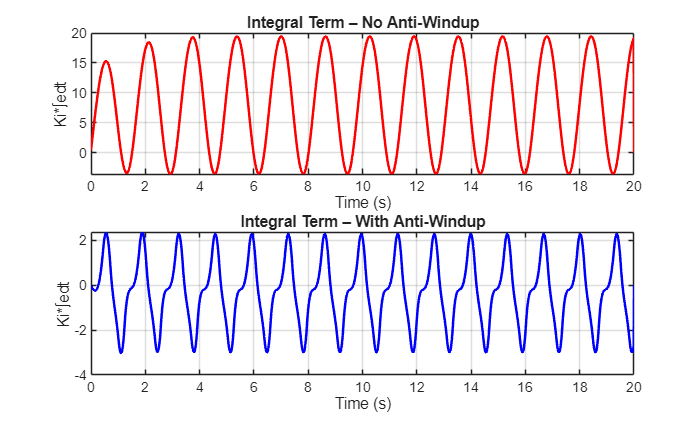

% Integral Term
figure;
subplot(2,1,1)
plot(t,I_term,'r','LineWidth',1.5)
grid on
title('Integral Term – No Anti-Windup')
xlabel('Time (s)'), ylabel('Ki*∫edt')

subplot(2,1,2)
plot(t,I1_term,'b','LineWidth',1.5)
grid on
title('Integral Term – With Anti-Windup')
xlabel('Time (s)'), ylabel('Ki*∫edt')

- Create a table showing quantitative improvement: 

- Maximum overshoot 

- Settling time 

- Time spent in saturation 

% Reference and tolerance
ref = 5;
tol = 0.02 * ref;   % 2% settling band

% Maximum overshoot
OS_noAW = (max(y) - ref)/ref * 100; % no Anti-Windup
OS_AW   = (max(y1) - ref)/ref * 100; % Anti-Windup

% Settling time (2%)
Ts_noAW = NaN; % NaN = Not a Number(i.e., undefined numeric result)
Ts_AW   = NaN;

for k = 1:N-1
    if all(abs(y(k:end) - ref) <= tol)
        Ts_noAW = t(k); % t(k) is settling time for no Anti-Windup
        break
    end
end

for k = 1:N-1
    if all(abs(y1(k:end) - ref) <= tol)
        Ts_AW = t(k); % t(k) is settling time for Anti-Windup
        break
    end
end

% Time spent in saturation
Tsat_noAW = sum(abs(u_sat) >= 9.999) * dt;
Tsat_AW   = sum(abs(u1_sat) >= 9.999) * dt;

% Create table
PerformanceTable = table( [OS_noAW; OS_AW], [Ts_noAW; Ts_AW], [Tsat_noAW; Tsat_AW], ...
    'VariableNames', {'MaxOvershoot_percent','SettlingTime_s','TimeInSaturation_s'}, ...
    'RowNames', {'Without_AntiWindup','With_AntiWindup'} );

disp(PerformanceTable)

                          MaxOvershoot_percent    SettlingTime_s    TimeInSaturation_s
                          ____________________    ______________    __________________

    Without_AntiWindup           113.96                NaN                15.81       
    With_AntiWindup              58.653                NaN                 12.9       



- Explain how anti-windup prevents excessive integral buildup

*Anti-windup prevents excessive integral buildup by ****making the integrator aware of actuator saturation****.When saturation occurs, u ≠ u_sat , and the difference (u_sat−u) feeds back into the integrator with opposite sign. This feedback counteracts the accumulation of error, effectively slowing down or reversing the growth of the integral term while the actuator is saturated.*

### Derivative Noise and Low-Pass Filtering:

- Add derivative action to create PID: Kp = 5, Ki = 8, Kd = 2 (use anti-windup from part b) 

- Add measurement noise to the feedback signal: ynoisy(t) = y(t)+0.05·randn(size(y))

`Without Filtering:`

- Calculate derivative as: u_d = K_d · (e − e_prev) / dt , where e uses noisy measurement

% Gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);

% Derivative filter time constant
tau_d = Kd / 10;

% Initialization
y = zeros(1,N);
y_dot = 0; y_ddot = 0;
y_noisy = zeros(1,N);

u_unsat = zeros(1,N);
u_sat = zeros(1,N);

int_err = 0;
d_filt = 0; % filtered derivative
e_prev = 0;

for k = 1:N-1

    % Measurement noise
    y_noisy(k) = y(k) + 0.05*randn;

    % Error (noisy measurement)
    e = r(k) - y_noisy(k);

    % Error derivative
    de = (e - e_prev)/dt;

    % Low-pass filtered derivative
    d_filt = d_filt + (dt/tau_d)*(de - d_filt);

    % Unsaturated PID control
    u_unsat(k) = Kp*e + Ki*int_err + Kd*d_filt; % u_d = Kd * d_filt

    % Actuator saturation
    u_sat(k) = max(min(u_unsat(k),10),-10);

    % Anti-windup integrator
    int_err = int_err + (e + (u_sat(k)-u_unsat(k))/Kt)*dt;

    % Plant dynamics
    y_tdot = 50*u_sat(k) - 20*y(k) - 25*y_dot - 8*y_ddot;
    y_ddot = y_ddot + y_tdot*dt;
    y_dot  = y_dot  + y_ddot*dt;
    y(k+1) = y(k)   + y_dot*dt;

    e_prev = e;
end

- Plot the control signal and observe the high-frequency oscillations

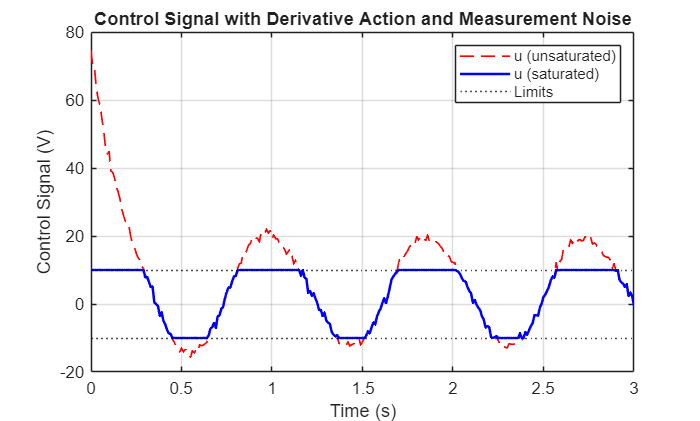

% Control Signal Plot
figure;
plot(t, u_unsat, 'r--', 'LineWidth', 1);
hold on;
plot(t, u_sat, 'b', 'LineWidth', 1.5);
yline(10,'k:'), yline(-10,'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal with Derivative Action and Measurement Noise');
legend('u (unsaturated)','u (saturated)','Limits');
xlim([0 3]); % zoom for comparision(shown further)

-  Plot the output response

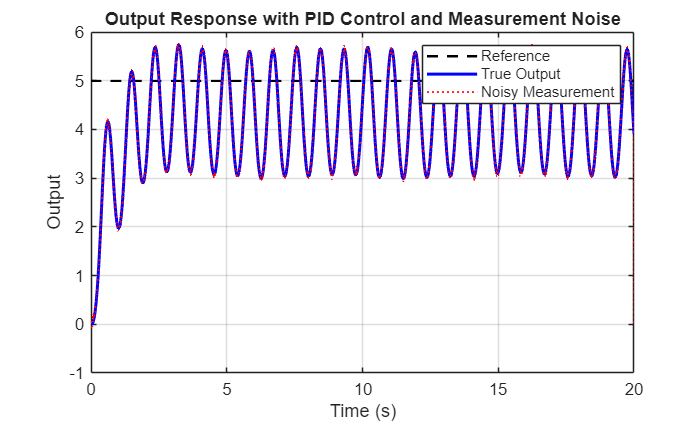

% Output Response
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
plot(t, y_noisy, 'r:', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response with PID Control and Measurement Noise');
legend('Reference','True Output','Noisy Measurement');

`With Low-Pass Filtering:`

- Implement filtered derivative: Instead of directly differentiating error, filter it first

- Use a simple first-order filter: e_d,filtered(k) = α · e_d,filtered(k−1) + (1−α) · e(k) 

- where, α = τ / (τ + dt) , with τ = 0.1

- Then calculate: u_d = K_d · (e_d,filtered − e_d,filtered,prev) / dt

% Gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);

% Filter parameter
tau = 0.1;
alpha = tau / (tau + dt);

% Initialization
y1 = zeros(1,N);
y1_dot = 0; y1_ddot = 0;
y1_noisy = zeros(1,N);

u1_unsat = zeros(1,N);
u1_sat = zeros(1,N);

int_err1 = 0;
e_filt = 0;
e_filt_prev = 0;

for k = 1:N-1

    % Noisy measurement
    y1_noisy(k) = y1(k) + 0.05*randn;

    % Error
    e1 = r(k) - y1_noisy(k);

    % Low-pass filtered error
    e_filt = alpha*e_filt + (1-alpha)*e1;

    % Derivative action from filtered error
    u1_d = Kd * (e_filt - e_filt_prev)/dt;

    % Unsaturated PID control
    u1_unsat(k) = Kp*e1 + Ki*int_err1 + u1_d;

    % Saturation
    u1_sat(k) = max(min(u1_unsat(k),10),-10);

    % Anti-windup integrator
    int_err1 = int_err1 + (e1 + (u1_sat(k)-u1_unsat(k))/Kt)*dt;

    % Plant dynamics
    y1_tdot = 50*u1_sat(k) - 20*y1(k) - 25*y1_dot - 8*y1_ddot;
    y1_ddot = y1_ddot + y1_tdot*dt;
    y1_dot  = y1_dot  + y1_ddot*dt;
    y1(k+1) = y1(k)   + y1_dot*dt;

    % Store previous filtered error
    e_filt_prev = e_filt;
end

- Plot the control signal and output response

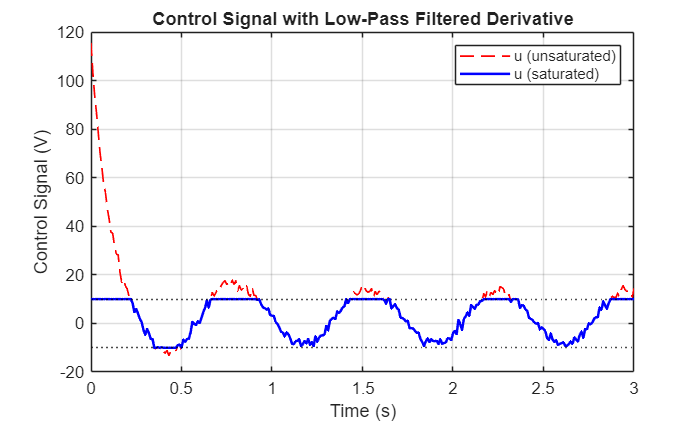

% Control Signal
figure;
plot(t, u1_unsat, 'r--', 'LineWidth', 1);
hold on;
plot(t, u1_sat, 'b', 'Linewidth', 1.5);
yline(10, 'k:'), yline(-10, 'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal with Low-Pass Filtered Derivative');
legend('u (unsaturated)','u (saturated)');
xlim([0 3])   % zoom to show noise reduction

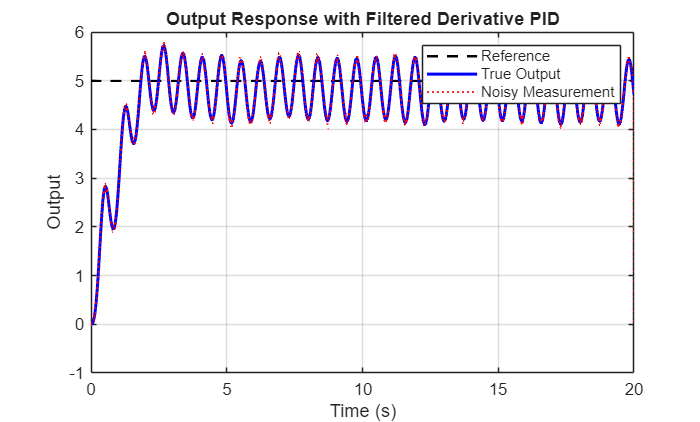

% Output Response
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y1, 'b', 'LineWidth', 1.8);
plot(t, y1_noisy, 'r:', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response with Filtered Derivative PID');
legend('Reference','True Output','Noisy Measurement');

`Create comparison plots showing:`

- Control signals (filtered vs unfiltered) - zoom in to see noise amplification

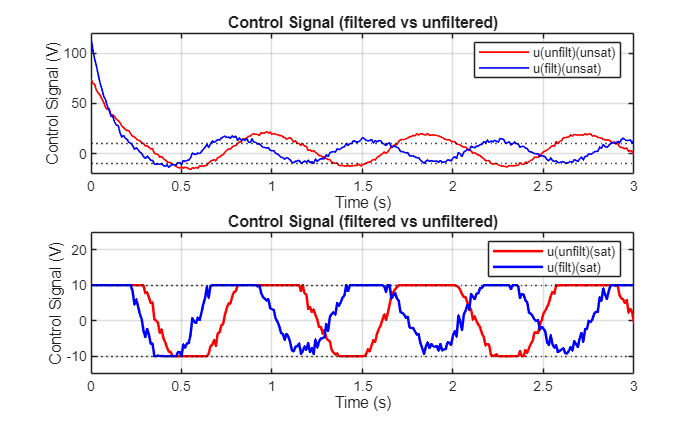

figure;
subplot(2,1,1)
plot(t, u_unsat, 'r', 'LineWidth', 1);
hold on;
plot(t, u1_unsat, 'b', 'LineWidth', 1);
yline(10, 'k:'), yline(-10, 'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal (filtered vs unfiltered)');
legend('u(unfilt)(unsat)','u(filt)(unsat)');
xlim([0 3])
ylim([-20 120])% zoom to show noise reduction

subplot(2,1,2)
plot(t, u_sat, 'r', 'Linewidth', 1.5);
hold on;
plot(t, u1_sat, 'b', 'Linewidth', 1.5);
yline(10, 'k:'), yline(-10, 'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal (filtered vs unfiltered)');
legend('u(unfilt)(sat)','u(filt)(sat)');
xlim([0 3])
ylim([-15 25])   % zoom to show noise reduction

- Output responses

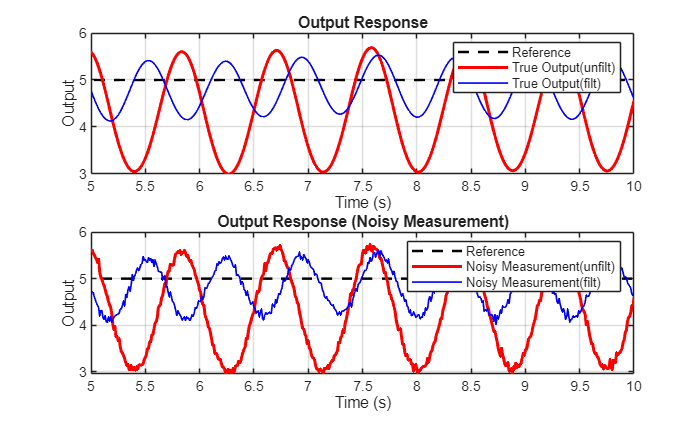

figure;
subplot(2,1,1)
plot(t, r, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.8);
plot(t, y1, 'b', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response');
legend('Reference','True Output(unfilt)','True Output(filt)');
xlim([5 10])

subplot(2,1,2)
plot(t, r, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y_noisy, 'r', 'LineWidth', 1.8);
plot(t, y1_noisy, 'b', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response (Noisy Measurement)');
legend('Reference','Noisy Measurement(unfilt)','Noisy Measurement(filt)');
xlim([5 10])

- Standard deviation of control signal in both cases

% Ignore first few seconds to incorporate only steady-state noise
t_start = 5;
idx = find(t >= t_start);

% Standard deviation of control signals
std_unfiltered = std(u_unsat(idx));
std_filtered   = std(u1_unsat(idx));

fprintf('Std (Unfiltered Derivative) = %.3f V\n', std_unfiltered);

Std (Unfiltered Derivative) = 11.282 V


fprintf('Std (Filtered Derivative)   = %.3f V\n', std_filtered);

Std (Filtered Derivative)   = 7.629 V


- Explain how filtering reduces noise amplification while maintaining damping effect

*Filtering removes high-frequency noise before differentiation, preventing noise amplification, while still preserving the low-frequency error changes needed for damping. As a result, the derivative term still reacts to genuine changes in system behavior, preserving its damping effect (reducing overshoot and oscillations).*

### Complex Trajectory Tracking:

-  Now implement your complete PID with anti-windup and derivative filtering

% PID Controller Gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);

% Simulation parameters
dt = 0.01;
t  = 0:dt:20;
N  = length(t);

- Test it on a realistic complex trajectory that combines multiple patterns:

% Reference trajectory
r = zeros(1,N);
for k = 1:N
    if t(k) < 2
        r(k) = 0.5*t(k);                          % ramp up
    elseif t(k) < 4
        r(k) = 1;                                % hold
    elseif t(k) < 8
        r(k) = 1 + 0.5*sin(2*pi*(t(k)-4));       % oscillation
    elseif t(k) < 10
        r(k) = 2;                                % step up
    elseif t(k) < 15
        r(k) = 2 - 0.3*(t(k)-10);                % ramp down
    else
        r(k) = 0.5;                              % final hold
    end
end

% Filter parameter
tau = 0.1;
alpha = tau / (tau + dt);

% Initialization
y = zeros(1,N);
y_dot = 0; y_ddot = 0;
y_noisy = zeros(1,N);

u_unsat = zeros(1,N);
u_sat = zeros(1,N);

int_err = 0;
e_filt = 0;
e_filt_prev = 0;

for k = 1:N-1

    % Noisy measurement
    y_noisy(k) = y(k) + 0.05*randn;

    % Error
    e = r(k) - y_noisy(k);

    % Low-pass filtered error
    e_filt = alpha*e_filt + (1-alpha)*e;

    % Derivative action from filtered error
    u_d = Kd * (e_filt - e_filt_prev)/dt;

    % Unsaturated PID control
    u_unsat(k) = Kp*e + Ki*int_err + u_d;

    % Saturation
    u_sat(k) = max(min(u_unsat(k),10),-10);

    % Tracking error
    tracking_error = r - y;

    % Anti-windup integrator
    int_err = int_err + (e + (u_sat(k)-u_unsat(k))/Kt)*dt;

    % Plant dynamics
    y_tdot = 50*u_sat(k) - 20*y(k) - 25*y_dot - 8*y_ddot;
    y_ddot = y_ddot + y_tdot*dt;
    y_dot  = y_dot  + y_ddot*dt;
    y(k+1) = y(k)   + y_dot*dt;

    % Store previous filtered error
    e_filt_prev = e_filt;
end

- Plot the reference trajectory, actual output, tracking error, and control signal

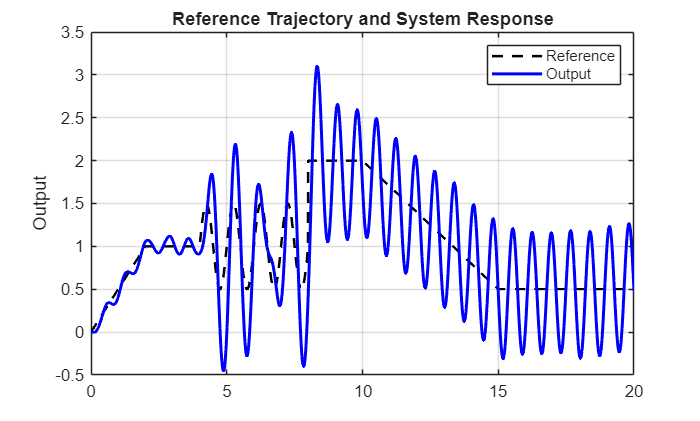

% Reference & Output
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
grid on;
ylabel('Output');
title('Reference Trajectory and System Response');
legend('Reference','Output');

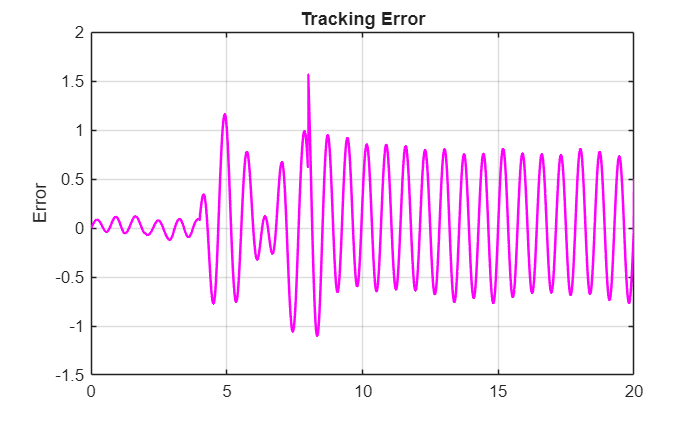

% Tracking Error
figure;
plot(t, tracking_error, 'm', 'LineWidth', 1.5);
grid on;
ylabel('Error');
title('Tracking Error');

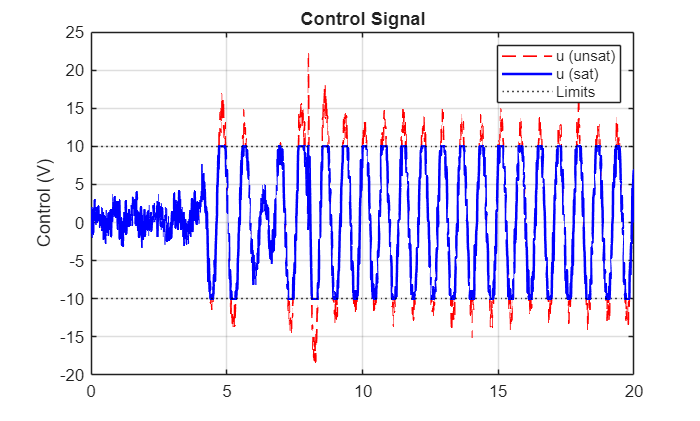


% Control Signal
figure;
plot(t, u_unsat, 'r--', 'LineWidth', 1); hold on;
plot(t, u_sat, 'b', 'LineWidth', 1.5);
yline(10,'k:'), yline(-10,'k:');
grid on;
ylabel('Control (V)');
title('Control Signal');
legend('u (unsat)','u (sat)','Limits');

- Calculate RMS tracking error: $e_{\textrm{RMS}} =\sqrt{\frac{1}{N}\sum_{i=1}^N e_i^2 }$

rms_error = sqrt(mean(tracking_error.^2));
fprintf ('RMS Error : %.4f\n', rms_error );

RMS Error : 0.4964


- Discuss how your controller handles different segments (ramp, step, sinusoid)

- Show that actuator limits are respected throughout

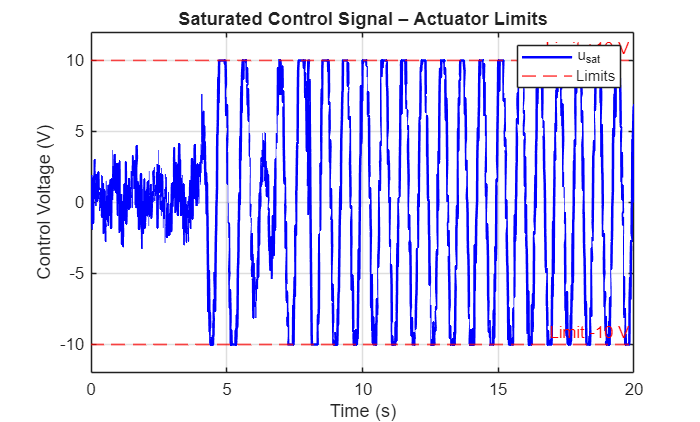

% Showing using saturated control signal plot
figure;
plot(t, u_sat, 'b', 'LineWidth', 1.5); hold on;
yline(10,'r--','Limit +10 V','LineWidth',1);
yline(-10,'r--','Limit -10 V','LineWidth',1);
grid on;
xlabel('Time (s)');
ylabel('Control Voltage (V)');
title('Saturated Control Signal – Actuator Limits');
legend('u_{sat}','Limits');
ylim([-12 12])